%addpath 'iwave\development\matlab'

load_parameters

t_end = 0.02; % secs
t = 0 : t_step : t_end;

load('data/get_tau_extra.mat')

L_Qs = length(Qs);
L_Ts = length(Ts);
L_reps = size(rmss, 1);

avg_rmss = mean(rmss, 1);
std_rmss = std(rmss, 1);
avg_std = mean(std_rmss, 'all')

avg_std = 73.6235

%{
best_taus = zeros(L_Qs, L_Ts);

for j = 1 : L_Qs
    Q_orig = Qs(j);
    %lins_rms = avg_lins_rms(1, j);
    
    for k = 1 : L_Ts
        T = Ts(k);
        
        [min_rms, min_index] = min(rmss(1,j,k,:));
        min_rms;
        best_taus(j, k) = taus(min_index);
        
        for m = 1 : size(rmss, 4)
            %tau = taus(m)
            %avg_rmss(1, j, k, m)
        end
    end
end

best_taus
%}

% alternative averaging method
best_taus2 = zeros(L_Qs, L_Ts);

for j = 1 : L_Qs
    Q_orig = Qs(j);
    %lins_rms = avg_lins_rms(1, j);
    
    for k = 1 : L_Ts
        T = Ts(k);
        
        this_taus = zeros(L_reps, 1);
        
        for l = 1 : L_reps
            % find which tau gave the smallest rms for this (Q, T, rep)
            [min_rms, min_index] = min(rmss(l,j,k,:));
            min_rms;
            this_taus(l) = taus(min_index);
            
            %for m = 1 : size(rmss, 4)
                %tau = taus(m)
                %avg_rmss(1, j, k, m)
            %end
        end
        
        % now remove the smallest tau and biggest tau
        [max_val, max_index] = max(this_taus);
        this_taus(max_index) = [];
        [min_val, min_index] = min(this_taus);
        this_taus(min_index) = [];
        
        best_taus2(j, k) = mean(this_taus);
        disp(" ")
    end
end

% insert extra taus
%{
count = 0
Ts_mod = 0

for k = 1 : L_Ts
    count = count + 1;
    best_taus(:,count) = best_taus2(:,k);
    Ts_mod(count) = Ts(k);
    if k == 5
        break
    end
    count = count + 1;
    best_taus(:,count) = ( best_taus2(:,k) + best_taus2(:,k+1) ) / 2;
    Ts_mod(count) = ( Ts(k) + Ts(k+1) ) / 2;
end

Ts = Ts_mod

L_Ts = 9
%}
best_taus2

best_taus2 = 	1.0e+-3 *

    0.2000    0.1722


best_taus = linspace(best_taus2(1), best_taus2(end), 9)

best_taus = 	1.0e+-3 *

    0.2000    0.1965    0.1931    0.1896    0.1861    0.1827    0.1792    0.1757    0.1722


L_Ts = 9

L_Ts = 9

Ts = linspace(10e-3, 50e-3, 9);


reps = 25

reps = 25

% 1 rep takes 7 min. 20 reps = 2h20 would be good. 25 rep was 160m=2h40

best_rmss = zeros(reps, L_Qs, L_Ts);
dynamic_powers = zeros(reps, L_Qs, L_Ts);
static_powers  = zeros(reps, L_Qs, L_Ts);

tic
done = 0;
num_runs = reps * L_Qs * L_Ts

num_runs = 225


% front to chop off
start_secs = 0.0015;
assert(start_secs < t(end)/3);
start = round(start_secs * f_sampling);

for l = 1 : reps
    f_axion = generate_axion_frequency_maxwellian(t, f_sampling, t_coherence, f_a, axion_linewidth);
    signal = generate_axion_signal(t, f_sampling, f_axion, axion_power_over_Q);
    noise = generate_thermal_noise(t);
    
    for j = 1 : L_Qs
        Q_orig = Qs(j);
        Q = Q_orig / heterodyning_ratio;
        
        band_width = f_a / Q; % or f_a_original / Q_orig
        limiting_band = [f_a-3*axion_linewidth, f_a+3*axion_linewidth];

        %noise_resonated = resonator_2(noise, f_a, band_width, f_sampling);
        %power_just_noise = bandpower(noise_resonated(start:end));
        
        signal_Qed = signal * sqrt(Q_orig);
        
        parfor k = 1 : L_Ts % par here
            T = Ts(k);
            
            noise_power = calculate_noise_power(f_sampling, T);
            noise_Ted = noise * sqrt(noise_power);
            
            tau = best_taus(j, k);
    
            [f_iwave, signal_dynamic] = do_iwave_and_resonator(t, noise_Ted, signal_Qed, f_a, band_width, f_sampling, limiting_band, tau);
            signal_static = resonator_2(noise_Ted + signal_Qed, f_a, band_width, f_sampling);
        
            the_rms = rms(f_iwave(start:end) - f_axion(start:end));
            best_rmss(l, j, k) = the_rms;

            dynamic_powers(l, j, k) = bandpower(signal_dynamic(start:end));
            static_powers (l, j, k) = bandpower(signal_static (start:end));
        end

        done = done + L_Ts;
        frac_done = done/num_runs;
        timer_elapsed = toc;
        time_total = timer_elapsed / frac_done;
        time_remaining = time_total - timer_elapsed;
        fprintf('done %d%%, %d min gone, %d min rem\n', round(100*frac_done), round(timer_elapsed/60), round(time_remaining/60))
    end
end

done 4%, 1 min gone, 23 min rem
done 8%, 2 min gone, 22 min rem
done 12%, 3 min gone, 21 min rem
done 16%, 4 min gone, 20 min rem
done 20%, 5 min gone, 19 min rem
done 24%, 6 min gone, 18 min rem
done 28%, 7 min gone, 17 min rem
done 32%, 8 min gone, 16 min rem
done 36%, 8 min gone, 15 min rem
done 40%, 9 min gone, 14 min rem
done 44%, 10 min gone, 13 min rem
done 48%, 11 min gone, 12 min rem
done 52%, 12 min gone, 11 min rem
done 56%, 13 min gone, 10 min rem
done 60%, 14 min gone, 9 min rem
done 64%, 15 min gone, 8 min rem
done 68%, 16 min gone, 8 min rem
done 72%, 17 min gone, 7 min rem
done 76%, 18 min gone, 6 min rem
done 80%, 19 min gone, 5 min rem
done 84%, 20 min gone, 4 min rem
done 88%, 21 min gone, 3 min rem
done 92%, 22 min gone, 2 min rem
done 96%, 23 min gone, 1 min rem
done 100%, 24 min gone, 0 min rem



save('data/got_tau_extra.mat', 'best_rmss', 'dynamic_powers', 'static_powers', 'L_Qs', 'L_Ts', 'Qs', 'Ts')

%load('data/got_tau_1.mat')

num = L_Qs * L_Ts;
Q_for_plot = zeros(1, num);
T_for_plot = zeros(1, num);
rms_for_plot = zeros(1, num);
ratio_for_plot = zeros(1, num);

best_rms_mean = zeros(L_Qs, L_Ts);
dynamic_mean  = zeros(L_Qs, L_Ts);
static_mean   = zeros(L_Qs, L_Ts);

% remove 5 smallest and 5 biggest values over the repeats
for j = 1 : L_Qs
    for k = 1 : L_Ts
        rms_reps = sort(best_rmss(:, j, k));
        static_reps = sort(static_powers(:, j, k));
        dynamic_reps = sort(dynamic_powers(:, j, k));
        
        % now remove the smallests and biggests
        rms_reps(1:5) = [];
        rms_reps(end-4:end) = [];
        static_reps(1:5) = [];
        static_reps(end-4:end) = [];
        dynamic_reps(1:5) = [];
        dynamic_reps(end-4:end) = [];
        
        best_rms_mean(j, k) = mean(rms_reps);
        dynamic_mean(j, k)  = mean(dynamic_reps);
        static_mean(j, k)   = mean(static_reps);
    end
end

%best_rms_mean = mean(best_rmss, 1);
%dynamic_mean = mean(dynamic_powers, 1);
%static_mean  = mean(static_powers,  1);

count = 0;
 
for j = 1 : L_Qs
    Q = Qs(j);
    
    for k = 1 : L_Ts
        count = count + 1;
        
        T = Ts(k);
        r = best_rms_mean(j, k);
%         if r > 500
%             r = 600
%         end
        
        Q_for_plot(count) = Q;
        T_for_plot(count) = T;
        rms_for_plot(count) = r;
        sm = max(dynamic_mean(:, k));
%         sm = static_mean(1, j, k);
%         if j ~= 1
%            if dynamic_mean(1, j-1, k) > sm
%                 [sm, in] = max(dynamic_mean(1, :, k));
%                 Qs(j)
%                 %sm = dynamic_mean(1, 5, k);
%            end
%         end
        ratio_for_plot(count) = dynamic_mean(j, k) / sm;
    end
end

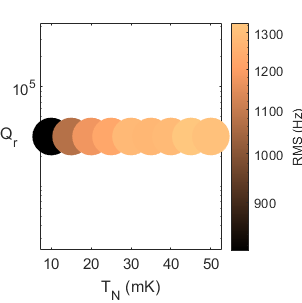

adstyle(8, 8)
%scatter(T_for_plot, Q_for_plot, 500, log(log(rms_for_plot)), 'filled')
%scatter(T_for_plot*1e3, Q_for_plot, 100000./log10(rms_for_plot).^5, rms_for_plot, 'filled')
scatter(T_for_plot*1e3, Q_for_plot, 800, rms_for_plot, 'filled')
%scatter(T_for_plot, Q_for_plot, 200000./rms_for_plot, rms_for_plot, 'filled')
set(gca, 'yscale','log')
set(gca, 'colorscale','log')
axis('padded')
c = colorbar();%'Ticks', [5e2 1e3 2e3 4e3]);
ylabel(c, 'RMS (Hz)')

yticks([1e5 1e6 1e7 1e8])

%map = [1*linspace(0, 1, 500).^.3' 0.38*linspace(0, 1, 500).^.3' (1 - linspace(0, 0.2, 500).^.3)']
%map(end,:)

% colorbar - need to find where there is no match - ie if you draw a line
% right through the middle, and that should be the end of the color scale
% p = bone in command window
%pink_alt = p(1:end*0.8,:);
%map = [pink_alt; repmat(pink_alt(end,:), 500, 1)];
%colormap(map)
colormap(copper)
box('on')
xlabel('T_N (mK)')
ylabel('Q_r')
set(get(gca,'ylabel'), 'rotation',0, 'VerticalAlignment','middle')
saveas(gca, 'figures/quality_of_lock.eps', 'epsc');

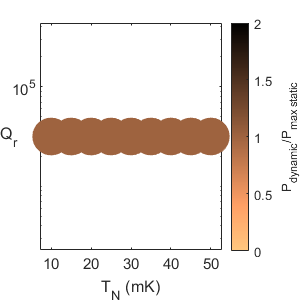

adstyle(8, 8)
scatter(T_for_plot*1e3, Q_for_plot, 800, ratio_for_plot, 'filled')
set(gca, 'yscale','log')
axis('padded')
c = colorbar();
ylabel(c, 'P_{dynamic}/P_{max static}')
colormap(flipud(copper))
box('on')
xlabel('T_N (mK)')
ylabel('Q_r')
set(get(gca,'ylabel'), 'rotation',0, 'VerticalAlignment','middle')

yticks([1e5 1e6 1e7 1e8])
saveas(gca, 'figures/main_results.eps', 'epsc');